# Object Detection with Machine Learning

This script replicates what was covered in the video "Object Detection with Machine Learning". Additionally, at the end are some useful metrics for evaluating detection results. You will later use these metrics for the final detection project.

### Loading the Ground Truth Data

The ground truth for the railroad signs dataset is stored in a ".mat" file in the course files. To access the ground truth data, you'll need to load it and then update the image file locations to match your system. To do this, run the following section of code.

load RRsignsGroundTruth.mat

Overwrite the image file locations stored in the ground truth variable to match your system.

testPath = overwriteGTruthLocations(gTruthTest,gTruthTrain);

### Training the ACF Object Detector

Convert the ground truth variable into a table that the function `trainACFObjectDetector` can use.

objectTrainingData = objectDetectorTrainingData(gTruthTrain)

Train the detector. This step may take a few minutes to run.

acfDetector = trainACFObjectDetector(objectTrainingData)

### Detect Using the Trained Detector

Run this section to apply the detector on the test images. First, load the test images as an image datastore.

imdsTest = imageDatastore(testPath)

Run the detector.

bboxes = detect(acfDetector,imdsTest)

Insert the ground truth and detection results over each image. The ground truth bounding boxes are added as green rectangles and the detected bounding boxes as a yellow rectangle with a detection score. If a yellow rectangle is missing, that means the detector missed a sign.

for idx = 1:height(imdsTest.Files)
    % Load the image
    img = readimage(imdsTest,idx);
    
    % Insert the ground truth bounding box
    img = insertShape(img,"Rectangle",gTruthTest.LabelData.RailRoadXingSign{idx},...
        "Color","green","LineWidth",10);
    
    % Insert the detected bounding box
    img = insertObjectAnnotation(img,"Rectangle",bboxes.Boxes{idx},...
        "Score: " + bboxes.Scores{idx},"FontSize",40,"LineWidth",6);
    
    % Display the image
    figure
    imshow(img)
end

### Evaluate the Results

Intersection over Union

A standard method for quantifying the accuracy of a single bounding box is to calculate its overlap ratio with the ground truth, also known as the Intersection over Union (IoU).

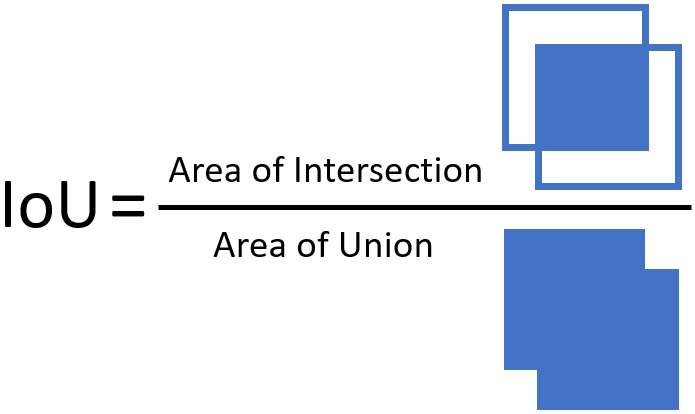

For example, here is the IoU value for one of the images.

idx = 4;
img = readimage(imdsTest,idx);
gTruthBbox = gTruthTest.LabelData.RailRoadXingSign{idx};
detectionBbox = bboxes.Boxes{idx};
img = insertShape(img,"filled-rectangle",gTruthBbox,"Color","green");
img = insertShape(img,"filled-rectangle",detectionBbox,"Color","red");
imshow(img)

overlapRatio = bboxOverlapRatio(gTruthBbox,detectionBbox)

A value of 0 means no overlap, and a value of 1 means perfect overlap.

Miss Rate and Precision

To measure the average performance of a detector over a collection of images, use the detection [miss rate](https://www.mathworks.com/help/vision/ref/evaluatedetectionmissrate.html) and [precision](https://www.mathworks.com/help/vision/ref/evaluatedetectionprecision.html). Both metrics count a detection as "correct" if its IoU is above a threshold value (0.5 by default).

**Miss Rate:** Quantifies how many ground truth objects received no correct detections. This metric is log-averaged over all detections and scales from:

- 0 - if **all** the ground truth objects were detected.

- 1 - if **none** of the ground truth objects were detected. 

evaluateDetectionMissRate(bboxes,gTruthTest.LabelData)

**Precision:** Quantifies how many detections were correct out of all detections. Note that if a ground truth object receives multiple detections, then only one of them is marked "correct". This metric is log-averaged over all detections and scales from:

- 0 - if **none** of the detections were correct.

- 1 - if **all** the detections were correct. 

evaluateDetectionPrecision(bboxes,gTruthTest.LabelData)

### Further Practice

In this example, the default trained detector missed the signs in 2 of the 10 test images, resulting in a miss rate of 0.2. See if you can adjust the options available for training the [`trainACFObjectDetector`](https://www.mathworks.com/help/vision/ref/trainacfobjectdetector.html) or [`detect`](https://www.mathworks.com/help/vision/ref/acfobjectdetector.detect.html) functions to achieve a lower miss rate without also reducing the precision.

% Put your code here



#### Helper Function

This function overwrites the image file locations stored in the ground truth variable to match your system.

function testPath = overwriteGTruthLocations(gTruthTest,gTruthTrain)
% Find the location of the image files
testPath = fileparts(which("RRXingSign_001.JPG"));
if isempty(testPath)
    error("The course files are not on the MATLAB search path." + ...
        "Follow the instructions when downloading the course files to add them to your path.")
end

% Overwrite locations for test images
currentPath = string(fileparts(gTruthTest.DataSource.Source{1}));
changeFilePaths(gTruthTest,[currentPath, testPath]);

% Overwrite locations for training images
trainPath = erase(testPath,'Test') + "Train";
currentPath = string(fileparts(gTruthTrain.DataSource.Source{1}));
changeFilePaths(gTruthTrain,[currentPath, trainPath]);
end

*Copyright 2022 The MathWorks, Inc.*